# Automatic identification of structural Unobserved Components models

## Introduction

In this document, several examples are run to show the operation and possibilities offered by the *UComp* software, a tool developed for the identification and forecasting of Unobserved Components models.

The source code of this toolbox has been written in C++ and supported by the functions of Armadillo library, so that its functionality has been extended to this platform by using MEX files.

It should be noted that the MEX function included in this set of files has been built in Windows 10 and 2019a version of Matlab, so if you are using a different OS and/or Matlab's version, you may not get the expected results. **See README.txt file**, where you will get information about this.

The following link will be very useful:

[https://es.mathworks.com/help/matlab/matlab_external/before-you-run-a-mex-file.html?lang=en](https://es.mathworks.com/help/matlab/matlab_external/before-you-run-a-mex-file.html?lang=en)

## UComp algorithm

UComp is an automatic estimation and prediction tool based on UC models. These models are very useful for operations such as smoothing, signal extraction, automatic outlier detection, seasonal adjustments, trends, etc. See the documentation forfdsa detailed information.

The following list shows the available functions and a brief description of what they do.

- Functions for creating and adjusting the parameters of UComp objects to control the behaviour of these functions. Time series data and its fundamental period are the only compulsory inputs required.

- UC - Overall function that runs all the rest.    

- UCsetup - Creates an UComp object and sets all input options controlling how the rest of functions work.

- UCmodel -  Runs *UCsetup* and *UCestim *sequentially.           

        2. Functions that works directly with UComp objects:

- UCestim - Identifies UC model, estimates it by Maximum Likelihood and computes forecasts.

- UCvalidate - Validates UC model previously estimated.

- UCfilter - Optimal Kalman filtering of UC models.

- UCsmooth - Optimal Fixed Interval Smoother.

- UCdisturb - Optimal Disturbance Smoother.

- UCcomponents - Components estimation.

## Examples                                                                                                                       

### Building MEX-file UComp.cpp (compulsory step if not Windows user)

Firstly, choose a C++ compiler

mex -setup c++

MEX configured to use 'MinGW64 Compiler (C++)' for C++ language compilation.
	 variables with more than 2^32-1 elements. You will be required
	 to update your code to utilize the new API.
	 You can find more information about this at:
	 <a href="https://www.mathworks.com/help/matlab/matlab_external/upgrading-mex-files-to-use-64-bit-api.html">https://www.mathworks.com/help/matlab/matlab_external/upgrading-mex-files-to-use-64-bit-api.html</a>.

To choose a different C++ compiler, select one from the following:
MinGW64 Compiler (C++)  mex -setup:C:\Users\urgne\AppData\Roaming\MathWorks\MATLAB\R2019a\mex_C++_win64.xml C++
Microsoft Visual C++ 2019  mex -setup:'C:\Program Files\MATLAB\R2019a\bin\win6

Build the souce code UCompC.cpp. Please, modify the next line with the path to your Armadillo (and LAPACK/BLAS libraries if necessary) include folder and library names and uncomment it.

%mex -Ipath\to\armadillo\include (-Lpath\to\blas-lapack\libraries) -llapack -lblas UCompC.cpp

### Airline Passengers data from Box et al.

In this folder is included an example of time series and his fundamental period, namely Airline Passegers, from Box et al. (2015).  This data will be used to show the power of the algorithms.

In first place, data is plotted to get an overview about the properties of time series. 

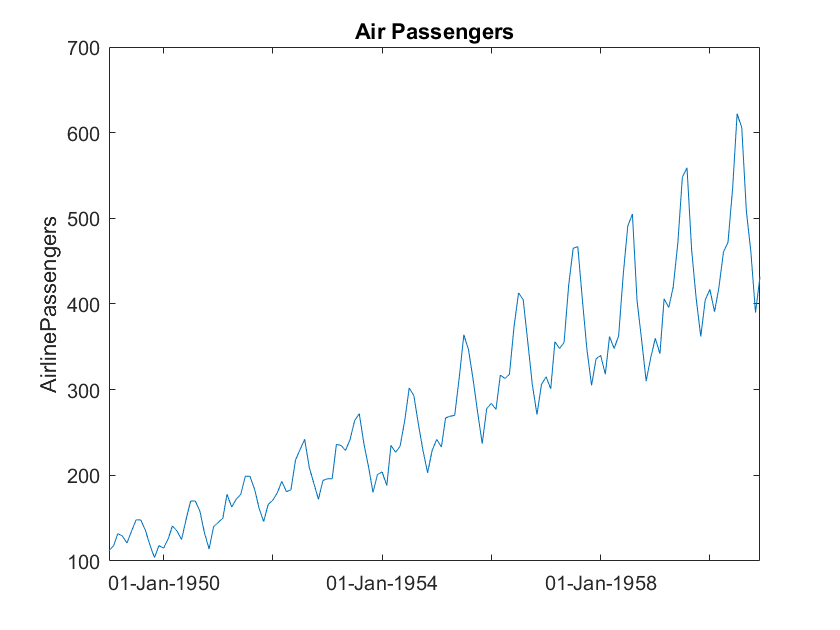

load 'airpassengers.mat'

yr = repmat((1949:1960), 12, 1);
mo = repmat((1:12)', 1, 12);
time = datestr(datenum(yr(:), mo(:), 1));
ts = timeseries(y(:), time, 'name', 'AirlinePassengers');
ts.TimeInfo.Format = 'dd-mmm-yyyy';

plot(ts)
title('Air Passengers')

As a first approach to the software, some different possibilities of entering input parameters are shown. For the introduction of optional variables, it is necessary to enter the name of the variable and then, the value (see the complete list of inputs typing *help UCsetup*)

%Just required inputs
m1 = UCsetup(log(y), frequency);
%Required inputs plus optional verbose mode
m2 = UCmodel(log(y), frequency, 'verbose', true); 

------------------------------------------------------------
 Identification started WITHOUT outlier detection
------------------------------------------------------------
          Model                       AIC      BIC     AICc
------------------------------------------------------------
       none/none/none/arma(0,0):   1.2554   1.2760   1.2554
           none/none/equal/none:   3.3487   3.5756   3.3626
      none/none/equal/arma(0,0):   1.7350   1.9825   1.7489
       none/none/different/none:   0.8451   1.1545   0.8659
  none/none/different/arma(0,0):   2.6504   2.9804   2.6782
              rw/none/none/none:  -1.6013  -1.5806  -1.6013
         rw/none/none/arma(0,0):  -1.0731  -1.0318  -1.0731
             rw/none/equal/none:  -2.8097  -2.5622  -2.7958
        rw/none/equal/arma(0,0):  -2.8148  -2.5467  -2.8009
         rw/none/different/none:  -2.8031  -2.4731  -2.7753
    rw/none/different/arma(0,0):  -2.8138  -2.4632  -2.7860
             llt/none/none/none:  -1.5157  -1.4

% Example of wrong format input
% %m3 = UCmodel(log(y), frequency, 'model', "llt/equal/arma(0,0)");

Now, UC identification is run using different information criteria. Let's start with Akaike's.

mAIC = UCmodel(log(y), frequency, 'criterion', 'aic');

------------------------------------------------------------
 Identification started WITHOUT outlier detection
------------------------------------------------------------
          Model                       AIC      BIC     AICc
------------------------------------------------------------
       none/none/none/arma(0,0):   1.2554   1.2760   1.2554
           none/none/equal/none:   3.3487   3.5756   3.3626
      none/none/equal/arma(0,0):   1.7350   1.9825   1.7489
       none/none/different/none:   0.8451   1.1545   0.8659
  none/none/different/arma(0,0):   2.6504   2.9804   2.6782
              rw/none/none/none:  -1.6013  -1.5806  -1.6013
         rw/none/none/arma(0,0):  -1.0731  -1.0318  -1.0731
             rw/none/equal/none:  -2.8097  -2.5622  -2.7958
        rw/none/equal/arma(0,0):  -2.8148  -2.5467  -2.8009
         rw/none/different/none:  -2.8031  -2.4731  -2.7753
    rw/none/different/arma(0,0):  -2.8138  -2.4632  -2.7860
             llt/none/none/none:  -1.5157  -1.4

fprintf("Optimal model with AIC criterion: %s", mAIC.model);

Optimal model with AIC criterion: llt/none/different/arma(0,0)

mAIC.criteria

ans = 1×4 table
     LLIK       AIC        BIC       AICc  
    ______    _______    _______    _______

    228.05    -2.9035    -2.5116    -2.8618


mBIC = UCmodel(log(y), frequency, 'criterion', 'bic');

------------------------------------------------------------
 Identification started WITHOUT outlier detection
------------------------------------------------------------
          Model                       AIC      BIC     AICc
------------------------------------------------------------
       none/none/none/arma(0,0):   1.2554   1.2760   1.2554
           none/none/equal/none:   3.3487   3.5756   3.3626
      none/none/equal/arma(0,0):   1.7350   1.9825   1.7489
       none/none/different/none:   0.8451   1.1545   0.8659
  none/none/different/arma(0,0):   2.6504   2.9804   2.6782
              rw/none/none/none:  -1.6013  -1.5806  -1.6013
         rw/none/none/arma(0,0):  -1.0731  -1.0318  -1.0731
             rw/none/equal/none:  -2.8097  -2.5622  -2.7958
        rw/none/equal/arma(0,0):  -2.8148  -2.5467  -2.8009
         rw/none/different/none:  -2.8031  -2.4731  -2.7753
    rw/none/different/arma(0,0):  -2.8138  -2.4632  -2.7860
             llt/none/none/none:  -1.5157  -1.4

fprintf("Optimal model with BIC criterion: %s", mBIC.model);

Optimal model with BIC criterion: llt/none/equal/arma(0,0)

mBIC.criteria

ans = 1×4 table
     LLIK       AIC        BIC       AICc  
    ______    _______    _______    _______

    222.55    -2.8827    -2.5733    -2.8619


mAICc = UCmodel(log(y), frequency, 'criterion', 'aicc');

------------------------------------------------------------
 Identification started WITHOUT outlier detection
------------------------------------------------------------
          Model                       AIC      BIC     AICc
------------------------------------------------------------
       none/none/none/arma(0,0):   1.2554   1.2760   1.2554
           none/none/equal/none:   3.3487   3.5756   3.3626
      none/none/equal/arma(0,0):   1.7350   1.9825   1.7489
       none/none/different/none:   0.8451   1.1545   0.8659
  none/none/different/arma(0,0):   2.6504   2.9804   2.6782
              rw/none/none/none:  -1.6013  -1.5806  -1.6013
         rw/none/none/arma(0,0):  -1.0731  -1.0318  -1.0731
             rw/none/equal/none:  -2.8097  -2.5622  -2.7958
        rw/none/equal/arma(0,0):  -2.8148  -2.5467  -2.8009
         rw/none/different/none:  -2.8031  -2.4731  -2.7753
    rw/none/different/arma(0,0):  -2.8138  -2.4632  -2.7860
             llt/none/none/none:  -1.5157  -1.4

fprintf("Optimal model with AICc criterion: %s", mAICc.model);

Optimal model with AICc criterion: llt/none/equal/arma(0,0)

mAICc.criteria

ans = 1×4 table
     LLIK       AIC        BIC       AICc  
    ______    _______    _______    _______

    222.55    -2.8827    -2.5733    -2.8619


Running *UCmodel* function allows the user to get information criteria and forecasted values.

Then, *UCvalidate* function is used to validate the estimated model.

mAIC = UCvalidate(mAIC);

-------------------------------------------------------------
  Concentrated Maximum-Likelihood
  Model: llt/none/different/arma(0,0)
  Periods:  12.0 /  6.0 /  4.0 /  3.0 /  2.4
  Q-Newton: Function convergence
  (*)  concentrated out parameter
  (**) constrained parameters during estimation
 -------------------------------------------------------------
                      Param          |T|    P-value     |Grad| 
 -------------------------------------------------------------
        Level:    2.34e-004          nan        nan  2.52e-005
        Slope:       0.0000**        nan        nan        nan
   Seas(12.0):    1.10e-005          nan        nan  2.53e-005
    Seas(6.0):    5.18e-006          nan        nan  4.27e-006
    Seas(4.0):       0.0000**        nan        nan        nan
    Seas(3.0):    2.19e-006          nan        nan  1.18e-005
    Seas(2.4):    1.22e-006          nan        nan  1.32e-005
    Irregular:    3.48e-004*         nan        nan        nan
 -----------

The following graph shows the values obtained from forecasting

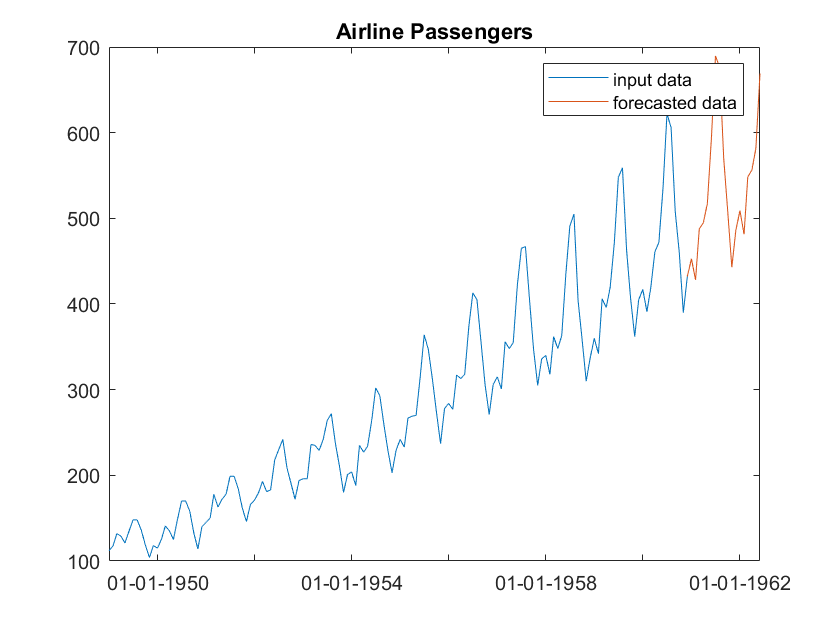

yrFor = repmat((1961:1962), 12, 1);
moFor = repmat((1:12)', 1, 2);
timeFor = datenum(yrFor(:), moFor(:), 1);
timeFor = datestr(timeFor(1 : end-6));
timeFor = ['01-Dec-1960'; timeFor];
tsFor = timeseries([y(end); exp(mAIC.yFor(:))], timeFor, 'name', 'AirPas Forecasted');
tsFor.TimeInfo.Format = 'dd-mm-yyyy';
plot(ts); hold on; plot(tsFor);
legend('input data', 'forecasted data');
title('Airline Passengers');
hold off

In addition, estimated components can be calculated with *UCcomponents*

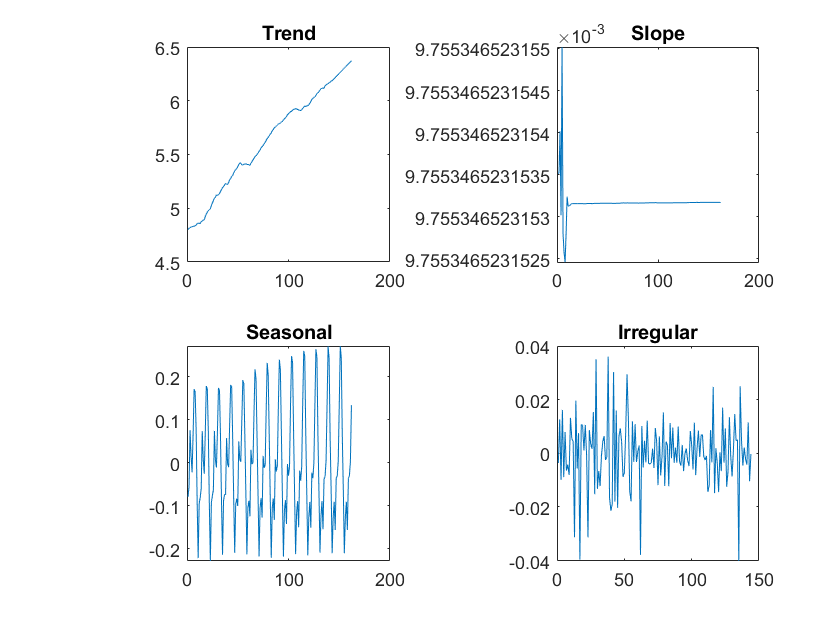

mAIC = UCcomponents(mAIC);
subplot(2,2,1); plot(mAIC.comp.Trend); title('Trend')
subplot(2,2,2); plot(mAIC.comp.Slope); title('Slope');
subplot(2,2,3); plot(mAIC.comp.Seasonal); title('Seasonal')
subplot(2,2,4); plot(mAIC.comp.Irregular); title('Irregular')

We can also include inputs in the model, represented by a variable named* u*.

u = zeros(3, 144);
u(1, 100 : 120) = 1;
u(2, 50) = 1;
u(3, 30) = 1;
m4 = UC(log(y), frequency, 'u', u,'verbose', true);

------------------------------------------------------------
 Identification started WITHOUT outlier detection
------------------------------------------------------------
          Model                       AIC      BIC     AICc
------------------------------------------------------------
       none/none/none/arma(0,0):   6.0390   6.1009   6.0390
           none/none/equal/none:   7.8382   8.1063   7.8521
      none/none/equal/arma(0,0):      nan      nan      nan
       none/none/different/none:   0.8265   1.1977   0.8612
  none/none/different/arma(0,0):   2.5512   2.9430   2.5929
              rw/none/none/none:   6.0390   6.1009   6.0390
         rw/none/none/arma(0,0):  -0.9445  -0.8414  -0.9445
             rw/none/equal/none:  -2.6416  -2.3323  -2.6208
        rw/none/equal/arma(0,0):  -2.6431  -2.3131  -2.6153
         rw/none/different/none:  -2.6268  -2.2349  -2.5851
    rw/none/different/arma(0,0):  -2.6366  -2.2241  -2.5949
             llt/none/none/none:  -1.3811  -1.2

Other options are outlier detection and cycles, as shown below.

m5 = UCmodel(log(y), frequency, 'verbose', true, 'outlier', 4);

------------------------------------------------------------
 Identification started WITH outlier detection
------------------------------------------------------------
          Model                       AIC      BIC     AICc
------------------------------------------------------------
       none/none/none/arma(0,0):   1.2554   1.2760   1.2554
           none/none/equal/none:   3.3487   3.5756   3.3626
      none/none/equal/arma(0,0):   1.7350   1.9825   1.7489
       none/none/different/none:   0.8451   1.1545   0.8659
  none/none/different/arma(0,0):   2.6504   2.9804   2.6782
              rw/none/none/none:  -1.6013  -1.5806  -1.6013
         rw/none/none/arma(0,0):  -1.0731  -1.0318  -1.0731
             rw/none/equal/none:  -2.8097  -2.5622  -2.7958
        rw/none/equal/arma(0,0):  -2.8148  -2.5467  -2.8009
         rw/none/different/none:  -2.8031  -2.4731  -2.7753
    rw/none/different/arma(0,0):  -2.8138  -2.4632  -2.7860
             llt/none/none/none:  -1.5157  -1.4538

Computing time of this output in comparison with that obtained for model m2 (line 14) shows that execution time increases considerably. One way to reduce this time is adding the optional* stepwise* input as true, which allows reducing the number of models to estimate.

m6 = UC(log(y), frequency, 'verbose', true, 'outlier', 4, 'stepwise', true);

------------------------------------------------------------
 Identification started WITH outlier detection
------------------------------------------------------------
          Model                       AIC      BIC     AICc
------------------------------------------------------------
           none/none/equal/none:   3.3487   3.5756   3.3626
      none/none/equal/arma(0,0):   1.7350   1.9825   1.7489
       none/none/different/none:   0.8451   1.1545   0.8659
  none/none/different/arma(0,0):   2.6504   2.9804   2.6782
             rw/none/equal/none:  -2.8097  -2.5622  -2.7958
        rw/none/equal/arma(0,0):  -2.8148  -2.5467  -2.8009
         rw/none/different/none:  -2.8031  -2.4731  -2.7753
    rw/none/different/arma(0,0):  -2.8138  -2.4632  -2.7860
            llt/none/equal/none:  -2.6393  -2.3505  -2.6184
       llt/none/equal/arma(0,0):  -2.8827  -2.5733  -2.8619
        llt/none/different/none:  -2.8082  -2.4370  -2.7735
   llt/none/different/arma(0,0):  -2.9035  -2.5116

fprintf("Optimal model: %s",m6.model);

Optimal model: llt/none/different/arma(0,0)

The same optimal model is obtained as in the m2 structure because the time serie does not present outliers.  However, this may be checked if any outliers are added artificially.

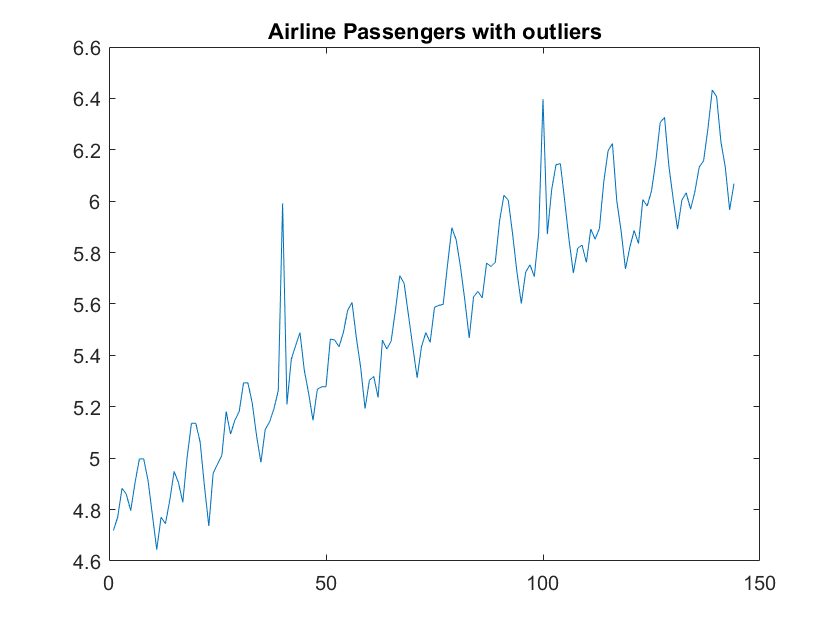

% For example, it is included two outliers in the samples 40 and 100
yMod = y;
yMod(40) = 400;
yMod(100) = 600;

figure; plot(log(yMod)); title('Airline Passengers with outliers')

m7 = UC(log(yMod), frequency, 'verbose', true, 'outlier', 4);

------------------------------------------------------------
 Identification started WITH outlier detection
------------------------------------------------------------
          Model                       AIC      BIC     AICc
------------------------------------------------------------
       none/none/none/arma(0,0):   1.2802   1.3008   1.2802
           none/none/equal/none:   2.7828   2.9685   2.7898
      none/none/equal/arma(0,0):   2.2410   2.4472   2.2479
       none/none/different/none:   0.8596   1.1071   0.8735
  none/none/different/arma(0,0):   2.3139   2.5820   2.3278
              rw/none/none/none:  -1.0561  -1.0148  -1.0561
         rw/none/none/arma(0,0):  -0.9172  -0.8553  -0.9172
             rw/none/equal/none:  -1.9570  -1.7095  -1.9431
        rw/none/equal/arma(0,0):  -1.9140  -1.6459  -1.9001
         rw/none/different/none:  -0.4368  -0.1687  -0.4229
    rw/none/different/arma(0,0):  -2.5229  -2.1930  -2.4952
             llt/none/none/none:  -1.2976  -1.1945

fprintf("Optimal model: %s", m7.model);

Optimal model: dt/none/equal/arma(0,0)

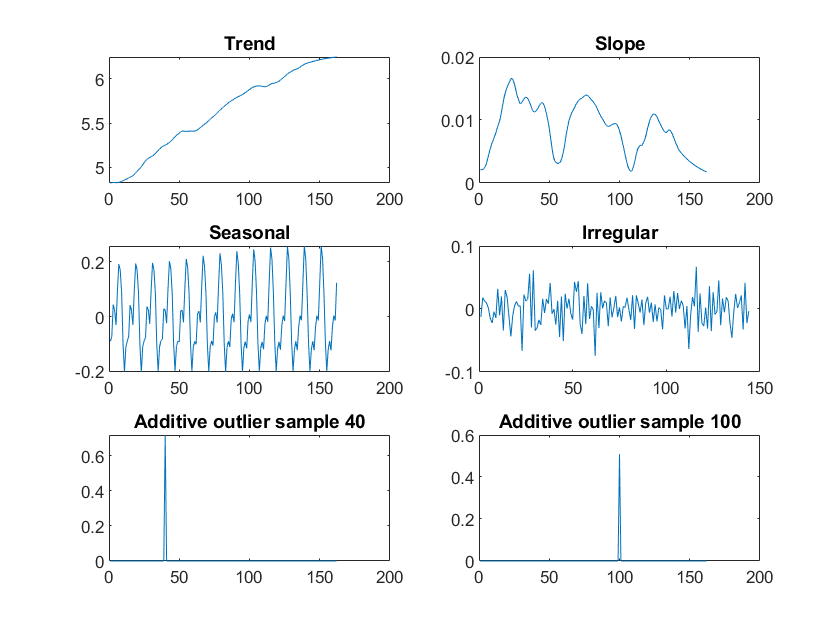

figure;
subplot(3,2,1); plot(m7.comp.Trend); title('Trend')
subplot(3,2,2); plot(m7.comp.Slope); title('Slope');
subplot(3,2,3); plot(m7.comp.Seasonal); title('Seasonal')
subplot(3,2,4); plot(m7.comp.Irregular); title('Irregular')
subplot(3,2,5); plot(m7.comp.AO40); title('Additive outlier sample 40')
subplot(3,2,6); plot(m7.comp.AO100); title('Additive outlier sample 100')

In case of setting cycles, the value must be indicated in variable named *model *using the 'trend/cycle/seasonal/irregular' format. The following call to *UC* tests for the existence of a cycle of approximate four years including the previous fake inputs. The results is that such cycle does not exist, since the outcome is a model without such cycle.

m8 = UC(log(y),frequency, 'u', u, 'verbose', true, 'outlier', 4, 'model', 'llt/-48?/eq/?');

------------------------------------------------------------
 Identification started WITH outlier detection
------------------------------------------------------------
          Model                       AIC      BIC     AICc
------------------------------------------------------------
               llt/none/eq/none:  -2.4731  -2.1225  -2.4453
          llt/none/eq/arma(0,0):  -2.7042  -2.3329  -2.6694
                llt/-48/eq/none:  -2.3852  -1.9727  -2.3435
           llt/-48/eq/arma(0,0):  -2.6240  -2.1909  -2.5754
------------------------------------------------------------
  Identification time:    2.68741 seconds
------------------------------------------------------------
-------------------------------------------------------------
  Concentrated Maximum-Likelihood
  Model: llt/none/eq/arma(0,0) + inputs
  Periods:  12.0 /  6.0 /  4.0 /  3.0 /  2.4
  Q-Newton: Function convergence
  (*)  concentrated out parameter
  (**) constrained parameters during estimation
 ---------

To sum up, **UComp** is a general software for UC modelling with a wide range of options that gives it high flexibility and power, especially due to the automatic identification facilities. See the documentation for detailed information of the inputs, outputs, functionalities and advantages of using this toolbox.